# **Численные методы в СПб АУ РАН - Часть 2**

## **Задание по практике №2**

Кузьмичев Артём, 4 курс

## **№15 (упражнения к разделу 9.1)**

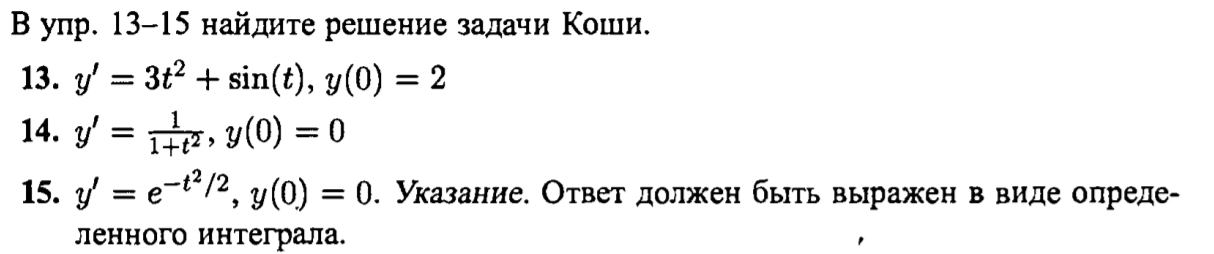

*Так как переменные уже разделены, осталось только проинтегрировать правую часть. Для выполнения условия Коши нижним пределом интегрирования должен быть 0 - тогда определённый интеграл будет обнуляться на верхнем пределе *$t=0$

Ответ:


$$y\left(t\right)=\int_0^t e^{{-t}^2 /2} \mathrm{dt}$$


Посмотрим, как решает такую задачу сам Matlab:

syms y(t) a
eqn = diff(y,t) == exp(-t^2/2);
cond = y(0) == 0;
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = \frac{\sqrt{2}\,\sqrt{\pi }\,\mathrm{erf}\left(\frac{\sqrt{2}\,t}{2}\right)}{2}$$

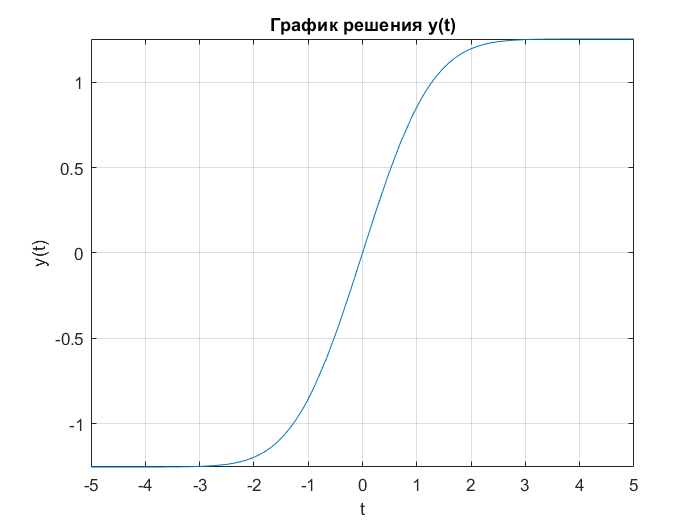

fplot(ySol)
grid on
title("График решения y(t)");
xlabel("t")
ylabel("y(t)")